# Basics of 4-pulse DEER signal simulation (2)

#### Author: Luis Fabregas

This tutorial is a continuation of the *"Basics of 4-pulse DEER signal simulation (1)"* tutorial.

## Preparing the components

Let's recycle the components we generated in the first part 

%Time-domain axis
t = linspace(-0.5,4,500); %us
%Time-domain axis
r = linspace(2,6,400); %nm

%Generate a distance distribution
rmean = 4; %nm
width = 0.8; %nm
P = rd_onegaussian(r,[rmean width]);

## Simulating form factors

Let's see how we can simullate form factors, i.e. dipolar evolution functions where only a fraction of the spins (the modulation depth)  are modulated and contribute to the dipolar signal, the rest leading to an unmodulated offset. To simuate these signals we must pass the modulation depth `lambda` as an optional parameter to the `dipolarsignal` function.

For our example we will take again the Gaussian distribution and assume a modulation depth of 40%. 

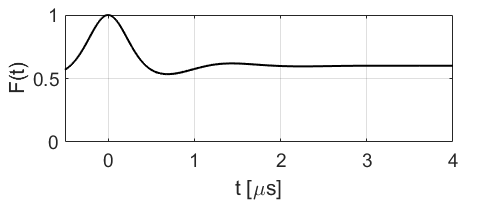

%Modulation depth
lambda = 0.4;

%Simulate form factor
F = dipolarsignal(t,r,P,'moddepth',lambda);

%Plot
figure('position',[0 0 500 200])
plot(t,F,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('t [\mus]'),ylabel('F(t)')
ylim([0 1])

#### Adding noise

While dipolar evolution functions are (virtually) not observable in experiments, form factors could be acquired under certain conditions. Still, all experimentally acquired signals are detected with superimposed noise. 

In DeerAnalysis we can add Gaussian-distributed white noise via the `'noiselevel'` option of `dipolarsignal`. The option just requires the noise standard deviation of the noise vector as input. Let's simulate our previous signal with a noise level of 0.02. 

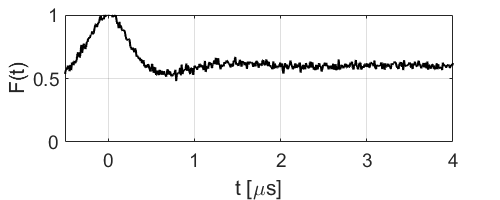

%Simulate form factor
F = dipolarsignal(t,r,P,'moddepth',lambda,'noiselevel',0.02);

%Plot
figure('position',[0 0 500 200])
plot(t,F,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('t [\mus]'),ylabel('F(t)')
ylim([0 1])

If we run this code section repeatedly we will see that the noise realization changes. This is due to the pseudorandom numbers changing with every execution. It is usually helpful to fix the noise realization by adding the `rng(number)` function at the start of a script. 

## Simulating form factors with background

As mentioned above, form factors are dipolar signals which we might detect under certains conditions. However, the most common form of primary signal is the one, in which the form factor has a background. 

The background function for 4-pulse DEER is easily modeled by an exponential function (in homogeneous media) or with a stretched exponential function (for fractal media). Let's first construct a fractal background using the stretched exponential function model `td_strexp` provided in DeerAnalysis. We will assume a decay rate k=0.25 and a fractal dimensionality d=2.7.

%Generate a fractal background
k = 0.25;
d = 2.7;
B = td_strexp(t,[k,d]);

Now in order to simulate add the background to our form factor we just need to pass the background as the self-explanatory `'background'` option of `dipolarsignal`. 

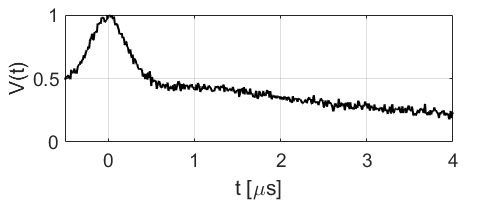

%Simulate dipolar signal
V = dipolarsignal(t,r,P,'moddepth',lambda,'background',B,'noiselevel',0.02);

%Plot
figure('position',[0 0 500 200])
plot(t,V,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('t [\mus]'),ylabel('V(t)')
ylim([0 1])

## Simulating a raw primary signal

While we are used to define our dipolar signal as functions which have their zero-time at an amplitude of 1, i.e. V(0)=1, due to re-scaling in the pre-processing, dipolar signals are not directly detected in that state. The signal is detected in some arbitrary units with arbitrary scales. Additionally, most spectrometers employ quadrature detection leading to dispersion of the real and imaginary parts of the dipolar signal. 

By means of the `'scale'` and `'phase'` options of `dipolarsignal`, we can simulate these effects as well. Let's try it out, assuming a scale of 1e8 and a quadrature phase of -pi/18. 

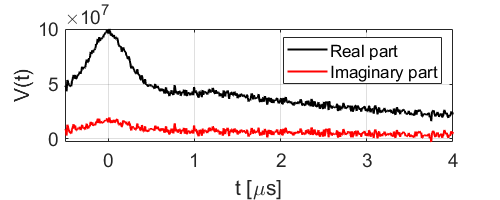

%Simulate dipolar signal
V = dipolarsignal(t,r,P,'moddepth',lambda,'background',B,'noiselevel',0.02,'phase',-pi/18,'scale',1e8);

%Plot
figure('position',[0 0 500 200])
plot(t,real(V),'k',t,imag(V),'r','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('t [\mus]'),ylabel('V(t)')
legend('Real part','Imaginary part')